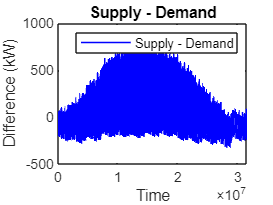

% 4CBLA30 EST modeling

% Import/extract data supply
data_supply = readmatrix("Team62_supply.csv","NumHeaderLines", 4);
time_supply_seconds = data_supply(:,1);
power_supply = data_supply(:,2);

% Import/extract data demand
data_demand = readmatrix("Team62_demand.csv", "NumHeaderLines", 4);
time_demand_seconds = data_demand(:,1);
power_demand = data_demand(:,2);

% Calculate the difference between supply and demand
difference = power_supply - power_demand;

% Plot the difference
plot(time_supply_seconds, difference, 'b', 'LineWidth', 1);

% Label the axes and add a title
xlabel('Time');
ylabel('Difference (kW)');
title('Supply - Demand');

% Add a legend
legend('Supply - Demand');


%calculate the difference in supply surplus and the demand deficit
total_difference = trapz(time_supply_seconds, difference);
disp('This is the difference between the supply surplus and the demand deficit');

This is the difference between the supply surplus and the demand deficit


disp(total_difference);

   6.3082e+08



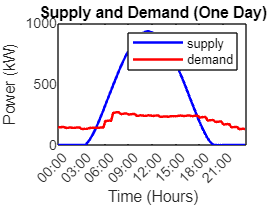

% Define the start and end time for the day
start_day = datetime(2023, 03, 23, 0, 0, 0); 
end_day = datetime(2023, 09, 23, 23, 59, 59); 

% Filter data for one day
index_supply_d = time_supply_datetime >= start_day & time_supply_datetime <= end_day;
time_supply_day = time_supply_datetime(index_supply_d);
power_supply_day = power_supply(index_supply_d);

index_demand_d = time_demand_datetime >= start_day & time_demand_datetime <= end_day;
time_demand_day = time_demand_datetime(index_demand_d);
power_demand_day = power_demand(index_demand_d);

% Plot with supply and demand for one day
plot(time_supply_day, power_supply_day, "b", "LineWidth", 1.5); 
hold on; 
plot(time_demand_day, power_demand_day, "r",  "LineWidth", 1.5); 
hold off;

xlim([start_day, end_day]);
datetick("x", "HH:00", "keeplimits");

xlabel("Time (Hours)");
ylabel("Power (kW)");
title("Supply and Demand (One Day)");
legend("supply", "demand");

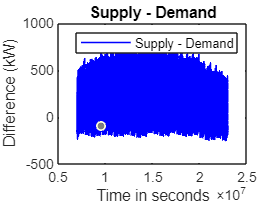

% Calculate the difference between supply and demand
difference_day = power_supply_day - power_demand_day;

% change time back to seconds 
time_back_seconds = seconds(time_supply_day - start_date);


% Plot the difference
plot(time_back_seconds, difference_day, 'b', 'LineWidth', 1);

% Label the axes and add a title
xlabel('Time in seconds');
ylabel('Difference (kW)');
title('Supply - Demand');

% Add a legend
legend('Supply - Demand');


%calculate the difference in supply surplus and the demand deficit
total_difference_day = trapz(time_back_seconds, difference_day);
disp('This is the difference per day between the supply surplus and the demand deficit');

This is the difference per day between the supply surplus and the demand deficit


disp(total_difference_day);

   2.0224e+09

